clear;
load Day_8_input.mat
% Part 1, layer containing fewest 0 digits. 25x6 layer.
% For this, treat a 25*6 layer as one blob of data
w_puzzle_input = reshape(puzzle_input,[25*6,100])';
for i = 1:size(w_puzzle_input,1)
    numzeros(i) = count(w_puzzle_input(i,:),'0');
end
nlayer = find(numzeros==min(numzeros))

nlayer = 14

ones = count(w_puzzle_input(nlayer,:),'1')

ones = 24

twos = count(w_puzzle_input(nlayer,:),'2'),

twos = 121

solution = ones*twos

solution = 2904


% Part 2
% Now we need all dimensions to check pixel by pixel, layer by layer
% Use numbers it's easier
%puzzle_input = '123456789012'
w_puzzle_input2 = str2double(string(cell2mat(split(puzzle_input,''))));
shape = [25,6,100];
%shape = [3,2,2]
w_puzzle_inputmat = permute(reshape(w_puzzle_input2,shape),[2,1,3])

w_puzzle_inputmat = w_puzzle_inputmat(:,:,1) =

     2     2     2     2     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     1     0
     2     2     2     2     2     2     2     0     1     2     2     2     0     2     0     2     2     2     2     2     2     2     0     2     2
     2     2     1     2     2     2     2     2     2     0     2     2     2     0     2     2     0     0     2     0     2     2     2     2     2
     2     0     0     1     2     2     2     2     2     2     2     2     2     1     2     2     2     2     2     2     2     2     2     2     2
     2     0     2     2     2     2     2     2     1     2     2     2     2     2     2     2     0     2     2     2     1     2     2     2     2
     2     2     2     1     2     2     2     2     2     0     2     2     2     2     2     2     1     2     2     2     2     0     2     2     2


w_puzzle_inputmat(:,:,2) =

     2     2    

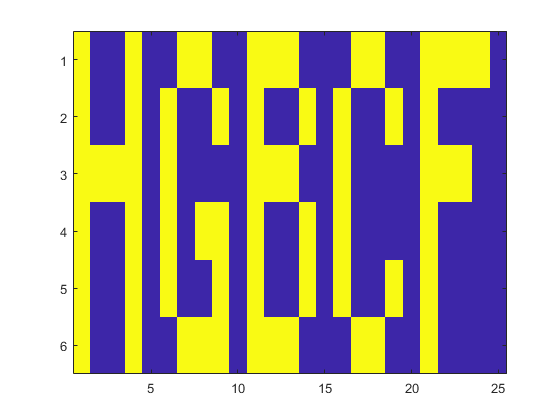

% Now get the first non-zero element when we remove the 2s
resulting_image = zeros(size(w_puzzle_inputmat,1), size(w_puzzle_inputmat,2));
for row = 1:size(w_puzzle_inputmat,1)
    for column = 1:size(w_puzzle_inputmat,2)
        layerstack = w_puzzle_inputmat(row,column,:)-2;
        layerstack = layerstack(:);
        [~,~,val] = find(layerstack,1);
        resulting_image(row,column) = val+2;
    end
end
image(resulting_image*255); % Solution

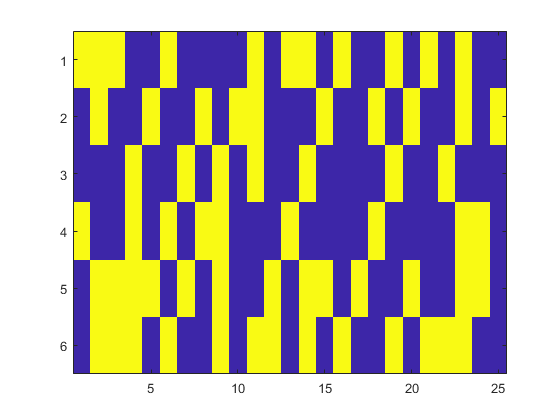

load Day_8_input.mat
k=1;
input_mat = zeros([6,25,100]);
for layer =1:100
    for column = 1:25
        for row = 1:6
            input_mat(row, column,layer) = str2double(puzzle_input(k)); k=k+1;
        end
    end
end
